clc;
clear;
syms s
syms ui uo u1 u2 u3 u4 u5 u6 i1 i2 i3 i4 i5 i6 i7
% syms L1 L2 L3 L4 L5 L6 L7 L8 L9 L10 L11 L12
% syms C1 C2 C3 C4 C5 C6

R=50;

L1=3.3e-9;
L2=0;
L3=8.2e-9;
L4=2.7e-9;
L5=8.2e-9;
L6=12e-9;
L7=8.2e-9;
L8=18e-9;
L9=7.5e-9;
L10=10e-9;
L11=8.2e-9;
L12=0;

C1=3E-12;
C2=6.8E-12;
C3=2.7E-12;
C4=2E-12;
C5=2.7E-12;
C6=3E-12;

eqs=[
    ui-u1==(i1+i2+i3+i4+i5+i6+i7)*L1*s;
    u1==i1*(L2*s+1/(C1*s));

    u1-u2==(i2+i3+i4+i5+i6+i7)*L3*s;
    u2==i2*(L4*s+1/(C2*s));

    u2-u3==(i3+i4+i5+i6+i7)*L5*s;
    u3==i3*(L6*s+1/(C3*s));

    u3-u4==(i4+i5+i6+i7)*L7*s;
    u4==i4*(L8*s+1/(C4*s));

    u4-u5==(i5+i6+i7)*L9*s;
    u5==i5*(L10*s+1/(C5*s));

    u5-u6==(i6+i7)*L11*s;
    u6==i6*(L12*s+1/(C6*s));

    u6==uo;
    uo==i7*R;
];
eqs=simplify(eqs)

eqs=replace_and_remove_first_equation(eqs,u1);
eqs=replace_and_remove_first_equation(eqs,i1);
eqs=replace_and_remove_first_equation(eqs,i2);
eqs=replace_and_remove_first_equation(eqs,i3);
eqs=replace_and_remove_first_equation(eqs,u3);
eqs=replace_and_remove_first_equation(eqs,u2);
eqs=replace_and_remove_first_equation(eqs,i4);
eqs=replace_and_remove_first_equation(eqs,u4);
eqs=replace_and_remove_first_equation(eqs,i7);
eqs=replace_and_remove_first_equation(eqs,u5);
eqs=replace_and_remove_first_equation(eqs,i5);
eqs=replace_and_remove_first_equation(eqs,u6);
eqs=replace_and_remove_first_equation(eqs,i6);
eqs=simplify(eqs)

uo=solve(eqs,uo)

gs=uo/ui;
gs=simplify(gs)

gw=@(w) subs(gs,s,1j*w);
real_gw=@(w) real(gw(w));
imag_gw=@(w) imag(gw(w));
point_770=[double(real_gw(770e6)),double(imag_gw(770e6))]

point_770 =     0.7920   -0.6462


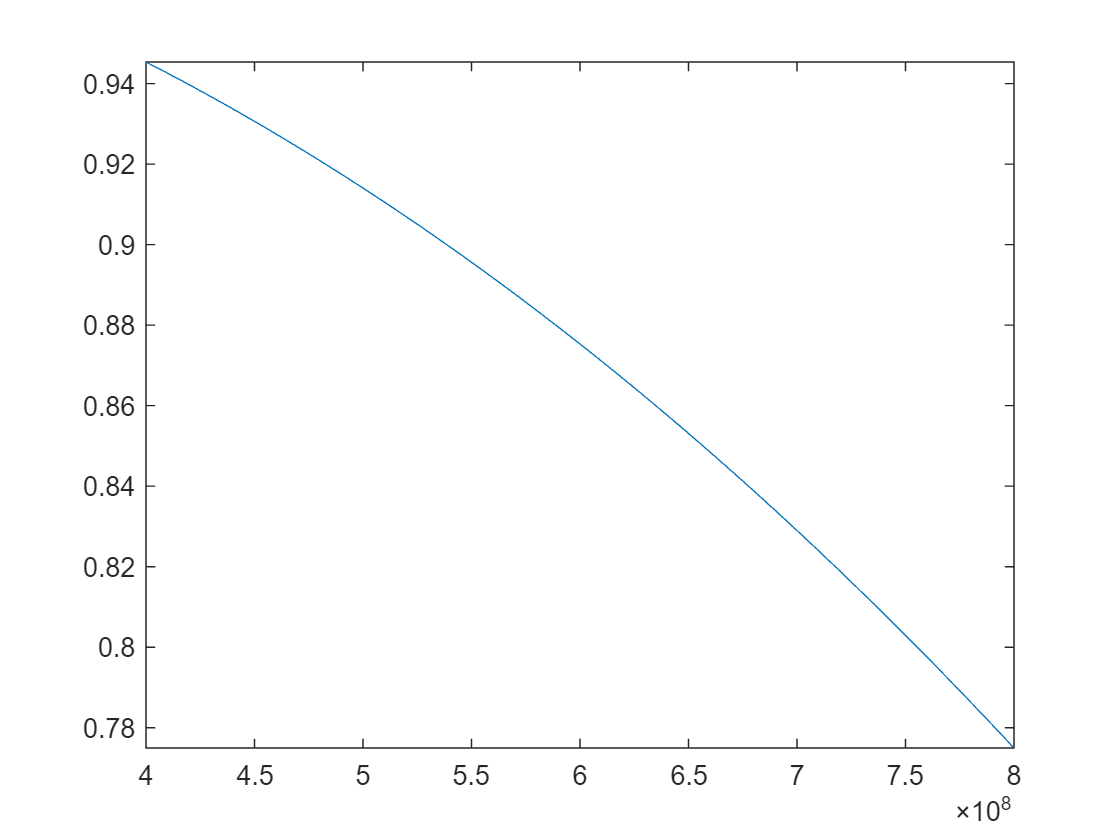

fplot(real_gw,[400e6,800e6])

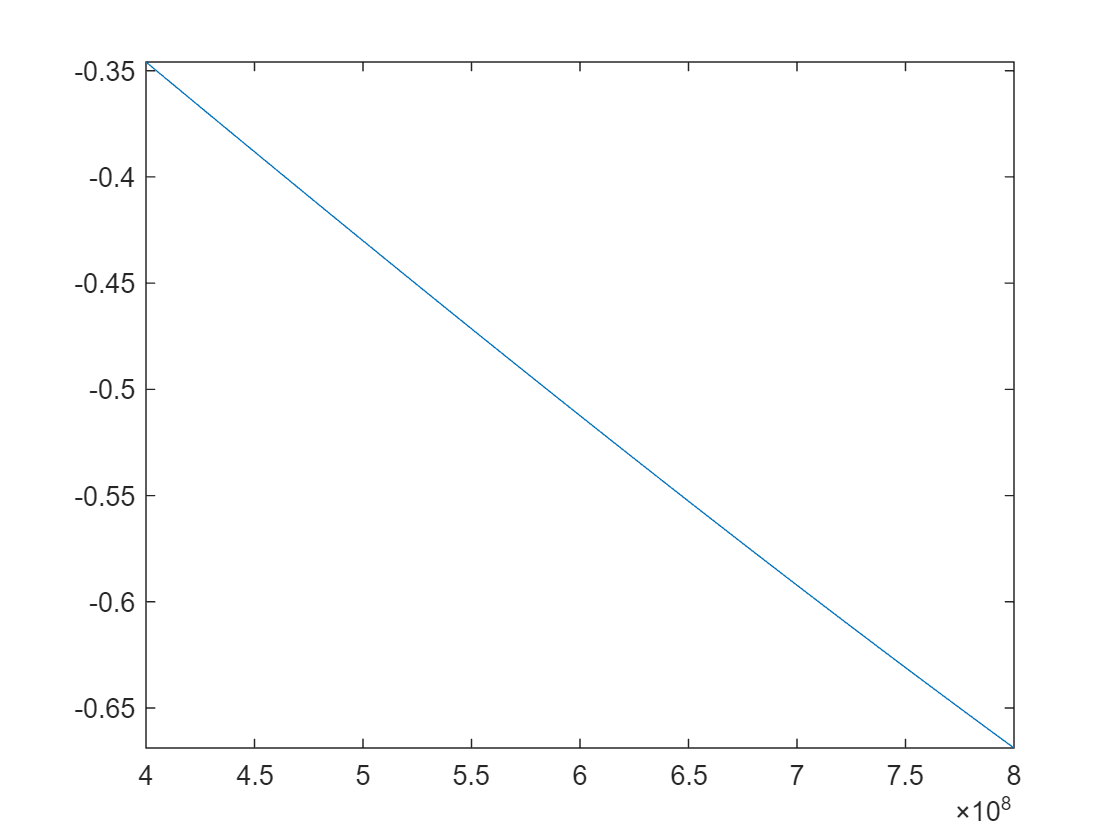

fplot(imag_gw,[400e6,800e6])